ropp_levels_path = '~/ags/projects/hiaper/code_ropp/ropp_11.0/ropp-11.0/ropp_io/data/ropp_thin_eum-247.dat';
% ropp_levels = fopen(ropp_levels_path);
% fread(ropp_levels)
table = readtable(ropp_levels_path);
a_levels = table.Var2;



path = 'output_no_waste/';
norp = 1;
plt_go = false;

pm_path_start = [path,'Output_alpha_'];
pm_path_end = '.txt';
info_path = '~/ags/projects/hiaper/2022.305_ar2023/nret/2023.015_iop16/';
occ_start = 1;
occ_end = 4;
sec_in_day = 86400;
start_day = 15; %2023.015
delta_height_pm = .4; %km

go_path = '~/ags/projects/hiaper/2022.305_ar2023/atmPrf/2023.015_iop16/';
go_name_start = 'atmPrf_N49T.2023.';
delta_go = .1;

%should I load the mat files instead? Did Pawel say something?
ropp_path_start = '~/ags/projects/hiaper/2022.305_ar2023/ropp_bangle_2d/2023.015_iop16/';
ropp_name_start = 'fm2d_N49T.2023.';
ropp_file_type = 'nc';
ropp_addition = 5; % number points below pm and go to plot ropp
delta_ropp = .15; %.1 plots but has gap

ropp_levels_path = '~/ags/projects/hiaper/code_ropp/ropp_11.0/ropp-11.0/ropp_io/data/ropp_thin_eum-247.dat';

if plt_go
    round_num = 1; %number points to right of decimal to round impact heights
else
    round_num = 2;
    table = readtable(ropp_levels_path);
    ropp_heights = table.Var2;
end

tolerance = 0.0001; %say doubles are equal if difference is less than this

lw = 4;
fs = 20;
tick_fs = 20;
clr = '#8ab5e3';
wide_clr = '#607e9e';



if norp == 1 %neg
    pm_insert = 'neg';
elseif norp == 0 %pos
    pm_insert = 'pos';
else %pos and neg
%     come back to this
end

%% same above %%

%hard-coded
file_start = 'Output_alpha';
occ_index_start = 18;
occ_index_end = 24;

len = length(file_start);
directory = dir(path);

count = 0;

for file = directory'

    tic
    
    if length(file.name) > 2

        if file.name(1:len) == file_start

            count = count + 1;
%             disp(count)

            occ_code = file.name(occ_index_start:occ_index_end);

            %below is graph_from_outputs
            occ_name = occ_code(occ_start:occ_end);
            info_file_path = [info_path,occ_name,'*'];
            info_dir = dir(info_file_path);
            folder_name = info_dir.name;
            
            %calc date from sow and sec_in_week
            %gps week starts on sunday
            %2023.01.15 is a sunday
            
            yaml_data = yaml.loadFile([info_path,folder_name,'/info.yaml']);
            sow = yaml_data.sow_low;
            dow = fix(sow/sec_in_day);
            day = start_day+dow; %should be 15 or 16

            Rc = yaml_data.Rc;
            aircraft_height = yaml_data.hgt_hi;
            aircraft_height_low = yaml_data.hgt_lo;
            
            sod = rem(sow,sec_in_day); %seconds of the day
            hour = fix(sod/3600); %hours of the day
            % hod_rem = rem(sod,3600); %how many seconds leftover after full hours
            % min = fix(hod_rem/60); %how many minutes leftover after full hours
            % sec = rem(min,60); %how many seconds leftover after full hours

            %phase matching             
            
            pm_data = importdata([pm_path_start,pm_insert,'_',occ_code,pm_path_end]);
            a_pm = pm_data(:,1);
            alpha_pm = pm_data(:,2);
            s(count).pm_alpha = alpha_pm;
            
            %geometric optics
            
            day_padded = sprintf('%03d', day);
            hour_padded = sprintf('%02d', hour);
            
            sat_name = occ_name(1:3);
            disp(sat_name)

            s(count).occ = occ_name;
%             s(count).impact_param = a_pm;

            ropp_path = strcat(ropp_path_start,ropp_name_start,day_padded,'.',hour_padded,'*',upper(sat_name),'*',ropp_file_type);
            ropp_dir = dir(ropp_path);
            ropp_file_name = ropp_dir.name;
            
            alpha_ropp = ncread([ropp_path_start,ropp_file_name],"bangle_bg");
            a_ropp = ncread([ropp_path_start,ropp_file_name],"impact_bg")/10^3;

            alpha_ropp_gen = ncread([ropp_path_start,ropp_file_name],"bangle");
            a_ropp_gen = ncread([ropp_path_start,ropp_file_name],"impact")/10^3;

            alpha_ropp_obs = ncread([ropp_path_start,ropp_file_name],"bangle_obs");
            a_ropp_obs = ncread([ropp_path_start,ropp_file_name],"impact_obs")/10^3;

            go_file_path = strcat(go_path,go_name_start,day_padded,'.',hour_padded,'*',upper(sat_name),'*');
            go_dir = dir(go_file_path);
            go_file_name = go_dir.name;
            
            alpha_go = ncread([go_path,go_file_name],"Bend_ang");
            a_go = ncread([go_path,go_file_name],"Impact_parm");
    
            alpha_go = flip(alpha_go);
            a_go = flip(a_go);

%             plot(a_go)
%             hold on
%             plot(a_ropp)
%             hold off
            figure
            plot(alpha_ropp, a_ropp, LineWidth = 2)
            hold on
            plot(alpha_ropp_gen, a_ropp_gen,LineWidth = 2)
            plot(alpha_ropp_obs, a_ropp_obs,LineWidth = 2)
            plot(alpha_go, a_go,LineWidth = 2)
            legend("Background","Generic","Observations","Geometric Optics")
            title("BA vs Impact Parameter")

            disp("hi")

        end
    end
end


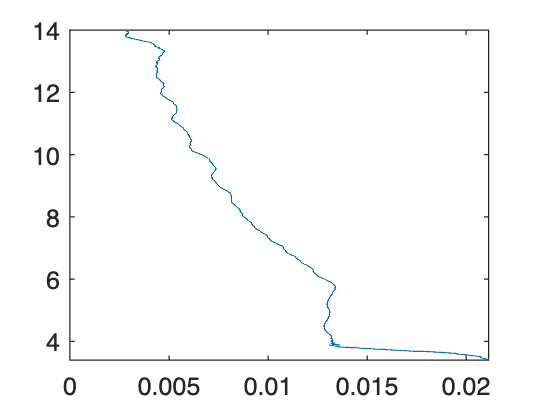

pm_data = importdata('ags/projects/hiaper/arivers/kate/phase_matching/code_pm_2018-11-14/Output_alpha_neg_r02r_r0.txt');
a_pm = pm_data(:,1);
alpha_pm = pm_data(:,2);
delta_height_pm = .4; %km
Rc = 6361.7111;

closest_ht = interp1(a_pm,a_pm,max(a_pm)-delta_height_pm,'nearest');
closest_ht_ind = find(a_pm == closest_ht);


a_pm = a_pm(1:closest_ht_ind);
alpha_pm = alpha_pm(1:closest_ht_ind);

plot(alpha_pm, a_pm- Rc)